# Taller 3

**Nombres:** Mariana Ramírez, Fernando Rojas y Jham Pool Murillo

## 1. Metodos directos para resolver sistemas lineales: 

### a.

#### a)

A = [2,-6,-1; -3,-1,7; -8,1,-2];
b = [-38;-34;-20];

**Solución exacta:**

x_exact = A(:,1:end-1) \ A(:,end);

disp('Solución exacta:');

Solución exacta:


disp(x_exact');

   -0.1202   -0.1327



**eliminación gaussiana **

 tic
[x_no_pivot, unique_solution] = solveLinearSystem([A, b]);

if unique_solution
    disp('Solución obtenida con eliminación gaussiana sin pivoteo:');
    disp(x_no_pivot');

else
    disp('No existe una solución única.');
end

Solución obtenida con eliminación gaussiana sin pivoteo:


    4.0000    8.0000   -2.0000



toc

Elapsed time is 0.003965 seconds.


**pivoteo parcial **

tic
x_partial = partialPivotingElimination([A, b]);

disp('Solución obtenida con eliminación gaussiana con pivoteo parcial:');

Solución obtenida con eliminación gaussiana con pivoteo parcial:


disp(x_partial');

     4     8    -2



toc

Elapsed time is 0.004401 seconds.


**pivoteo escalado**

tic
x_scaled = scaledPartialPivotingElimination([A, b]);

disp('Solución obtenida con eliminación gaussiana con pivoteo escalado:');

Solución obtenida con eliminación gaussiana con pivoteo escalado:


disp(x_scaled');

     4     8    -2



toc

Elapsed time is 0.003897 seconds.


A = [0,-3,7; 1,2,-1; 5,-2,0];
b = [2;3;2];

**Solución exacta:**

x_exact = A(:,1:end-1) \ A(:,end);

disp('Solución exacta:');

Solución exacta:


disp(x_exact');

   -0.5317   -1.6032



**eliminación gaussiana **

tic
[x_no_pivot, unique_solution] = solveLinearSystem([A, b]);

if unique_solution
    disp('Solución obtenida con eliminación gaussiana sin pivoteo:');
    disp(x_no_pivot');

else
    disp('No existe una solución única.');
end

Solución obtenida con eliminación gaussiana sin pivoteo:


    0.9855    1.4638    0.9130



toc

Elapsed time is 0.002669 seconds.


**pivoteo parcial **

tic
x_partial = partialPivotingElimination([A, b]);

disp('Solución obtenida con eliminación gaussiana con pivoteo parcial:');

Solución obtenida con eliminación gaussiana con pivoteo parcial:


disp(x_partial');

    0.9855    1.4638    0.9130



toc

Elapsed time is 0.003340 seconds.


**pivoteo escalado**

tic
x_scaled = scaledPartialPivotingElimination([A, b]);

disp('Solución obtenida con eliminación gaussiana con pivoteo escalado:');

Solución obtenida con eliminación gaussiana con pivoteo escalado:


disp(x_scaled');

    0.9855    1.4638    0.9130



toc

Elapsed time is 0.003328 seconds.


#### b)

A = [3, -0.1, -0.2;
     0.1, 7, -0.3;
     0.3, -0.2, 10];
b = [7.85; -19.3; 71.4];

**Solución exacta:**

x_exact = A(:,1:end-1) \ A(:,end);

disp('Solución exacta:');

Solución exacta:


disp(x_exact');

    0.2636   -0.0850



**eliminación gaussiana **

tic;
[x_no_pivot, unique_solution] = solveLinearSystem([A, b]);

if unique_solution
    disp('Solución obtenida con eliminación gaussiana sin pivoteo:');
    disp(x_no_pivot');
else
    disp('No existe una solución única.');
end

Solución obtenida con eliminación gaussiana sin pivoteo:


    3.0000   -2.5000    7.0000



time_no_pivot = toc;

**pivoteo parcial **

tic;
x_partial = partialPivotingElimination([A, b]);

disp('Solución obtenida con eliminación gaussiana con pivoteo parcial:');

Solución obtenida con eliminación gaussiana con pivoteo parcial:


disp(x_partial');

    3.0000   -2.5000    7.0000



time_partial = toc;

**pivoteo escalado**

tic;
x_scaled = scaledPartialPivotingElimination([A, b]);

disp('Solución obtenida con eliminación gaussiana con pivoteo escalado:');

Solución obtenida con eliminación gaussiana con pivoteo escalado:


disp(x_scaled');

    3.0000   -2.5000    7.0000



time_scaled = toc;

### b.

#### a)

A = [2,-6,-1; -3,-1,7; -8,1,-2;0,-3,7; 1,2,-1; 5,-2,0];
b = [-38;-34;-20;2;3;2];

% Definimos la matriz A y el vector b para el primer caso
A1 = [2, -6, -1;
     -3, -1, 7;
     -8, 1, -2];
b1 = [-38; -34; -20];

% Definimos la matriz A y el vector b para el segundo caso
A2 = [3, -0.1, -0.2;
     0.1, 7, -0.3;
     0.3, -0.2, 10];
b2 = [7.85; -19.3; 71.4];

% Factorizamos la matriz A en las matrices L y U
[L1, U1] = luFactorization(A1);
[L2, U2] = luFactorization(A2);

% Resolvemos los sistemas lineales triangulares para obtener x
x1 = U1 \ (L1 \ b1);
x2 = U2 \ (L2 \ b2);

% Creamos el vector c para calcular la columna n-ésima de M
c1 = zeros(size(A1, 1), 1);
c1(end) = 1;
c2 = zeros(size(A2, 1), 1);
c2(end) = 1;

% Resolvemos Ld = c y Ux = d para obtener M
d1 = L1 \ c1;
M1 = U1 \ d1;
d2 = L2 \ c2;
M2 = U2 \ d2;

% Mostramos los resultados
disp('Solución del sistema para el primer caso:');

Solución del sistema para el primer caso:


disp(x1');

    4.0000    8.0000   -2.0000



disp('Matriz inversa para el primer caso:');

Matriz inversa para el primer caso:


disp(M1);

   -0.1153
   -0.0295
   -0.0536



disp('Solución del sistema para el segundo caso:');

Solución del sistema para el segundo caso:


disp(x2');

    3.0000   -2.5000    7.0000



disp('Matriz inversa para el segundo caso:');

Matriz inversa para el segundo caso:


disp(M2);

    0.0068
    0.0042
    0.0999



#### b)

A = [3, -0.1, -0.2;
     0.1, 7, -0.3;
     0.3, -0.2, 10];
b = [7.85; -19.3; 71.4];

% Factorización LU de A
[L, U] = luFactorization(A);

% Resolver Ly = b y Ux = y
y = L \ b;
x = U \ y;

% Crear el vector c para calcular la columna n-ésima de M
c = zeros(size(A, 1), 1);
c(end) = 1;

% Resolver Ld = c y Ux = d para obtener M
d = L \ c;
M = U \ d;

% Mostrar resultados
disp('Solución del sistema:');

Solución del sistema:


disp(x');

    3.0000   -2.5000    7.0000



disp('Matriz inversa:');

Matriz inversa:


disp(M);

    0.0068
    0.0042
    0.0999



## 2. Metodos iterativos para resolver sistemas lineales

### a.

A = [15, -3, -1;
     -3, 18, -6;
     -4, -1, 12];
b = [3800; 1200; 2350];

TOL = 0.001; 
max_iteraciones = 1000;
x0 = zeros(size(b));

**Jacobi**

[x_jacobi, success_jacobi] = jacobiMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Jacobi:');

Solución con el método de Jacobi:


disp(x_jacobi');

  253.3333   66.6667  195.8333




error_jacobi = norm(A * x_jacobi - b) / norm(b);
disp(['Error relativo: ', num2str(error_jacobi * 100), '%']);

Error relativo: 48.6582%


**Gauss-Siedel**

[x_gauss_seidel, success_gauss_seidel] = gaussSeidelMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Gauss-Seidel:');

Solución con el método de Gauss-Seidel:


disp(x_gauss_seidel');

  253.3333  108.8889  289.3519




error_gauss_seidel = norm(A * x_gauss_seidel - b) / norm(b);
disp(['Error relativo: ', num2str(error_gauss_seidel * 100), '%']);

Error relativo: 39.8195%


Como podemos ver la aproximación más cercana es la de Gauss-Siedel

### b.

#### i.

A = [2,-6,-1; -3,-1,7; -8,1,-2];
b = [-38;-34;-20];

TOL = 0.001; 
max_iteraciones = 1000;
x0 = zeros(size(b));

**Jacobi**

[x_jacobi, success_jacobi] = jacobiMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Jacobi:');

Solución con el método de Jacobi:


disp(x_jacobi');

   -19    34    10




error_jacobi = norm(A * x_jacobi - b) / norm(b);
disp(['Error relativo: ', num2str(error_jacobi * 100), '%']);

Error relativo: 567.2184%


**Gauss-Siedel**

[x_gauss_seidel, success_gauss_seidel] = gaussSeidelMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Gauss-Seidel:');

Solución con el método de Gauss-Seidel:


disp(x_gauss_seidel');

  -19.0000   91.0000  131.5000




error_gauss_seidel = norm(A * x_gauss_seidel - b) / norm(b);
disp(['Error relativo: ', num2str(error_gauss_seidel * 100), '%']);

Error relativo: 2086.7251%


#### ii.

A = [0,-3,7; 1,2,-1; 5,-2,0];
b = [2;3;2];

TOL = 0.001; 
max_iteraciones = 1000;
x0 = zeros(size(b));

**Jacobi**

[x_jacobi, success_jacobi] = jacobiMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Jacobi:');

Solución con el método de Jacobi:


disp(x_jacobi');

       Inf    1.5000       Inf




error_jacobi = norm(A * x_jacobi - b) / norm(b);
disp(['Error relativo: ', num2str(error_jacobi * 100), '%']);

Error relativo: NaN%


**Gauss-Siedel**

[x_gauss_seidel, success_gauss_seidel] = gaussSeidelMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Gauss-Seidel:');

Solución con el método de Gauss-Seidel:


disp(x_gauss_seidel');

   Inf  -Inf  -Inf




error_gauss_seidel = norm(A * x_gauss_seidel - b) / norm(b);
disp(['Error relativo: ', num2str(error_gauss_seidel * 100), '%']);

Error relativo: NaN%


Hacemos un cambio en la primera fila, ya que como vimos anteriormente nos sale infinito al tener un 0 en la diagonal principal

A = [0,-3,7; 1,2,-1; 5,-2,0];
b = [2;3;2];

aux = A(1,:);
auxb = b(1);
 
A(1,:) = A(3,:);
b(1) = b(3);
b(3) = auxb;
A(3,:) = aux;

TOL = 0.001; 
max_iteraciones = 1000;
x0 = zeros(size(b));

**Jacobi**

[x_jacobi, success_jacobi] = jacobiMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Jacobi:');

Solución con el método de Jacobi:


disp(x_jacobi');

    0.4000    1.5000    0.2857




error_jacobi = norm(A * x_jacobi - b) / norm(b);
disp(['Error relativo: ', num2str(error_jacobi * 100), '%']);

Error relativo: 131.2005%


**Gauss-Siedel**

[x_gauss_seidel, success_gauss_seidel] = gaussSeidelMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Gauss-Seidel:');

Solución con el método de Gauss-Seidel:


disp(x_gauss_seidel');

    0.4000    1.3000    0.8429




error_gauss_seidel = norm(A * x_gauss_seidel - b) / norm(b);
disp(['Error relativo: ', num2str(error_gauss_seidel * 100), '%']);

Error relativo: 66.29%


#### iii.

A = [3, -0.1, -0.2;
     0.1, 7, -0.3;
     0.3, -0.2, 10];
b = [7.85; -19.3; 71.4];

TOL = 0.001; 
max_iteraciones = 1000;
x0 = zeros(size(b));

**Jacobi**

[x_jacobi, success_jacobi] = jacobiMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Jacobi:');

Solución con el método de Jacobi:


disp(x_jacobi');

    2.6167   -2.7571    7.1400




error_jacobi = norm(A * x_jacobi - b) / norm(b);
disp(['Error relativo: ', num2str(error_jacobi * 100), '%']);

Error relativo: 3.467%


**Gauss-Siedel**

[x_gauss_seidel, success_gauss_seidel] = gaussSeidelMethod(size(b, 1), A, b, x0, TOL, max_iteraciones);

disp('Solución con el método de Gauss-Seidel:');

Solución con el método de Gauss-Seidel:


disp(x_gauss_seidel');

    2.6167   -2.7945    7.0056




error_gauss_seidel = norm(A * x_gauss_seidel - b) / norm(b);
disp(['Error relativo: ', num2str(error_gauss_seidel * 100), '%']);

Error relativo: 3.2029%


### c.

#### i.

A = [2, -6, -1; -3, -1, 7; -8, 1, -2];
b = [-38; -34; -20];

[x_refined_i, COND_i] = iterativeRefinement(A, b, 1000, 1e-5, 5);

disp('Aproximación refinada:');

Aproximación refinada:


disp(x_refined_i');

     4     8    -2



disp(['COND:', num2str(COND_i)]);

COND:1.0953e-11


#### ii.

A = [0, -3, 7; 1, 2, -1; 5, -2, 0];
b = [2; 3; 2];

aux = A(1,:);
auxb = b(1);
 
A(1,:) = A(3,:);
b(1) = b(3);
b(3) = auxb;
A(3,:) = aux;

[x_refined_ii, COND_ii] = iterativeRefinement(A, b, 1000, 1e-5, 5);

disp('Aproximación refinada:');

Aproximación refinada:


disp(x_refined_ii');

    0.9855    1.4638    0.9130



disp(['COND:', num2str(COND_ii)]);

COND:1.2311e-11


#### iii.

A = [3, -0.1, -0.2; 0.1, 7, -0.3; 0.3, -0.2, 10];
b = [7.85; -19.3; 71.4];
[x_refined_iii, COND_iii] = iterativeRefinement(A, b, 1000, 1e-5, 5);

disp('Aproximación refinada:');

Aproximación refinada:


disp(x_refined_iii');

    3.0000   -2.5000    7.0000



disp(['COND:', num2str(COND_iii)]);

COND:2.0277e-11


## 3. Regresión por mínimos cuadrados: 

### a.

syms x

X = [5 10 15 20 25 30 35 40 45 50];
Y = [17 24 31 33 37 37 40 40 42 41];

- Ajuste los datos a una línea recta

[m, b] = ajusteLinealMinimosCuadrados(X, Y);

fprintf('La ecuación de la línea recta ajustada es: y = %.4fx + %.4f\n', m, b);

La ecuación de la línea recta ajustada es: y = 0.4945x + 20.6000



Y_ajuste_linea = m * X + b;

- Ajuste los datos a un modelo de tasa de crecimiento de saturación. 

[ajuste_a, ajuste_b] = ajusteCrecimientoSaturacion(X, Y);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('El valor ajustado de a es: %.4f\n', ajuste_a);

El valor ajustado de a es: 50.5295


fprintf('El valor ajustado de b es: %.4f\n', ajuste_b);

El valor ajustado de b es: 10.1295



Y_ajuste_saturacion = ajuste_a * X ./ (ajuste_b + X);

- Ajuste los datos a una ecuación de potencias. 

[a, b] = ajustePotencias(X, Y);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('El valor ajustado de a es: %.4f\n', a);

El valor ajustado de a es: 11.4278


fprintf('El valor ajustado de b es: %.4f\n', b);

El valor ajustado de b es: 0.3433



Y_ajuste_potencias = a * X.^b;

- Ajuste los datos a una parábola. 

[a, b,c] = ajusteParabola(X, Y);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('El valor ajustado de a es: %.4f\n', a);

El valor ajustado de a es: -0.0161


fprintf('El valor ajustado de b es: %.4f\n', b);

El valor ajustado de b es: 1.3779


fprintf('El valor ajustado de c es: %.4f\n', c);

El valor ajustado de c es: 11.7667



Y_ajuste_parabola = a * X.^2 + b * X + c;

- Grafique la tabla de datos y los ajustes encontrados en el intervalo en que están contenidos los datos. 

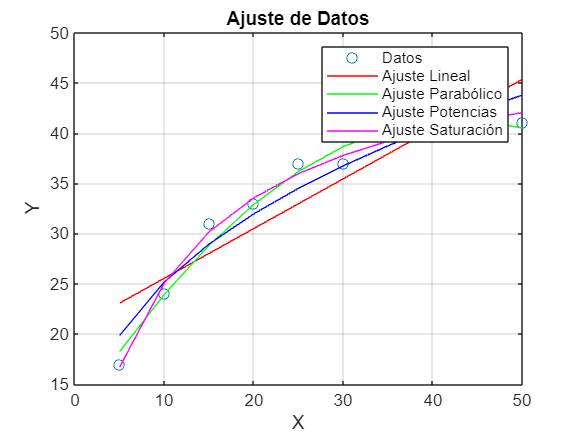

figure;
plot(X, Y, 'o', 'DisplayName', 'Datos');
hold on;
plot(X, Y_ajuste_linea, 'r', 'DisplayName', 'Ajuste Lineal');
plot(X, Y_ajuste_parabola, 'g', 'DisplayName', 'Ajuste Parabólico');
plot(X, Y_ajuste_potencias, 'b', 'DisplayName', 'Ajuste Potencias');
plot(X, Y_ajuste_saturacion, 'm', 'DisplayName', 'Ajuste Saturación');
xlabel('X');
ylabel('Y');
title('Ajuste de Datos');
legend;
grid on;

-  ¿Existe algun ajuste superior a los demás? Justifique.

fprintf('Coeficiente de determinación (R^2):\n');

Coeficiente de determinación (R^2):



R_cuadrado_linea = 1 - sum((Y - Y_ajuste_linea).^2) / sum((Y - mean(Y)).^2);
fprintf('Ajuste Lineal: %.4f\n', R_cuadrado_linea);

Ajuste Lineal: 0.8385



R_cuadrado_parabola = 1 - sum((Y - Y_ajuste_parabola).^2) / sum((Y - mean(Y)).^2);
fprintf('Ajuste Parabólico: %.4f\n', R_cuadrado_parabola);

Ajuste Parabólico: 0.9800



R_cuadrado_potencias = 1 - sum((Y - Y_ajuste_potencias).^2) / sum((Y - mean(Y)).^2);
fprintf('Ajuste Potencias: %.4f\n', R_cuadrado_potencias);

Ajuste Potencias: 0.9488



R_cuadrado_saturacion = 1 - sum((Y - Y_ajuste_saturacion).^2) / sum((Y - mean(Y)).^2);
fprintf('Ajuste Saturación: %.4f\n', R_cuadrado_saturacion);

Ajuste Saturación: 0.9894


El ajuste parabólico y el ajuste de saturación son superiores a los demás debido a sus coeficientes de determinación (*R^*2) más altos. El ajuste parabólico explica el 98.00% de la variabilidad en los datos (*R^*2=0.9800), mientras que el ajuste de saturación explica el 98.94% de la variabilidad (*R^*2=0.9894). En comparación, el ajuste lineal y el ajuste de potencias tienen coeficientes de determinación más bajos, lo que sugiere que estos modelos pueden no capturar tan bien la relación entre las variables *X* e *Y* en los datos proporcionados.

### b.

X = [3 4 5 7 8 9 11 12];
Y = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6];

#### • Aproxime los datos mediante un polinomio genérico de grado 3, grado 4 y grado 5. 

% Ajuste polinomial de grado 3
coeficientes_grado_3 = ajustePolinomial(X, Y, 3);
disp(['Coeficientes para el ajuste polinomial de grado ', 3, ':']);

Coeficientes para el ajuste polinomial de grado □:


disp(coeficientes_grado_3);

    0.0467
   -1.0412
    7.1438
  -11.4887




% Ajuste polinomial de grado 4
coeficientes_grado_4 = ajustePolinomial(X, Y, 4);
disp(['Coeficientes para el ajuste polinomial de grado ', 4, ':']);

Coeficientes para el ajuste polinomial de grado □:


disp(coeficientes_grado_4);

   -0.0082
    0.2892
   -3.5544
   17.8734
  -27.2372




% Ajuste polinomial de grado 5
coeficientes_grado_5 = ajustePolinomial(X, Y, 5);
disp(['Coeficientes para el ajuste polinomial de grado ', 5, ':']);

Coeficientes para el ajuste polinomial de grado □:


disp(coeficientes_grado_5);

   -0.0008
    0.0230
   -0.1591
   -0.5182
    8.2494
  -15.8784



#### • Aproxime los datos mediante funciones ortogonales (Polinomios de Legendre). 

% Ajuste utilizando polinomios de Legendre de grado 3
coeficientes_leg_3 = ajusteLegendre(X, Y, 3);
disp(['Coeficientes para el ajuste polinomial de grado ', 3, ':']);

Coeficientes para el ajuste polinomial de grado □:


disp(coeficientes_leg_3);

$$\left(\begin{array}{cccc} 3.5644810267858701990917325019836 & -0.049396205357147948689089389517903 & 0.080641741071421080278014414943755 & 1.0456938920454206254362361505628 \end{array}\right)$$


% Ajuste utilizando polinomios de Legendre de grado 4
coeficientes_leg_4 = ajusteLegendre(X, Y, 4);
disp(['Coeficientes para el ajuste polinomial de grado ', 3, ':']);

Coeficientes para el ajuste polinomial de grado □:


disp(coeficientes_leg_4);

$$\left(\begin{array}{ccccc} 3.5644810267858701990917325019836 & -0.049396205357147948689089389517903 & 0.080641741071421080278014414943755 & 1.0456938920454206254362361505628 & -1.5136957183441666074941167607903 \end{array}\right)$$


% Ajuste utilizando polinomios de Legendre de grado 5
coeficientes_leg_5 = ajusteLegendre(X, Y, 5);
disp(['Coeficientes para el ajuste polinomial de grado ', 3, ':']);

Coeficientes para el ajuste polinomial de grado □:


disp(coeficientes_leg_5);

$$\left(\begin{array}{cccccc} 3.5644810267858701990917325019836 & -0.049396205357147948689089389517903 & 0.080641741071421080278014414943755 & 1.0456938920454206254362361505628 & -1.5136957183441666074941167607903 & -0.76135688530212064506486058235168 \end{array}\right)$$

#### • Grafique la tabla de datos y los polinomios de aproximación obtenidos en el intervalo en que están contenidos los datos. 

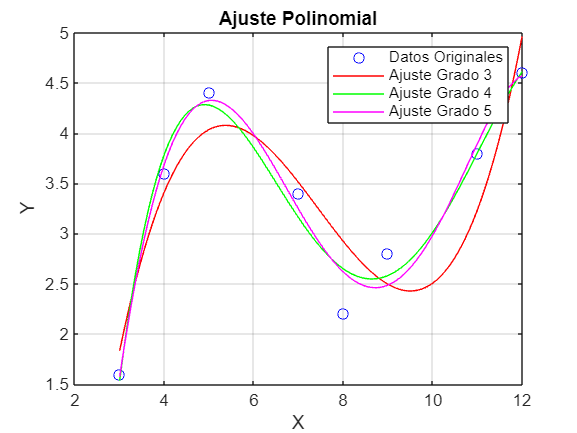

% Definir el intervalo para la gráfica
intervalo = linspace(min(X), max(X), 100);

% Calcular los valores de Y para cada intervalo utilizando los coeficientes del ajuste
Y_aprox_3 = polyval(coeficientes_grado_3, intervalo);
Y_aprox_4 = polyval(coeficientes_grado_4, intervalo);
Y_aprox_5 = polyval(coeficientes_grado_5, intervalo);

% Graficar los datos originales
figure;
plot(X, Y, 'bo', 'DisplayName', 'Datos Originales');
hold on;

% Graficar los polinomios de aproximación
plot(intervalo, Y_aprox_3, 'r-', 'DisplayName', 'Ajuste Grado 3');
plot(intervalo, Y_aprox_4, 'g-', 'DisplayName', 'Ajuste Grado 4');
plot(intervalo, Y_aprox_5, 'm-', 'DisplayName', 'Ajuste Grado 5');

% Configuración de la gráfica
title('Ajuste Polinomial');
xlabel('X');
ylabel('Y');
legend('show');
grid on;

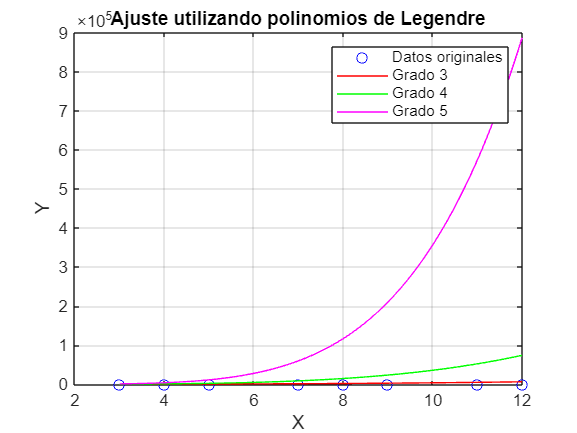

% Intervalo para evaluar los polinomios de aproximación
x_intervalo = linspace(min(X), max(X), 100);

% Evaluar los polinomios de aproximación en el intervalo
y_leg_3 = polyval(double(coeficientes_leg_3), x_intervalo);
y_leg_4 = polyval(double(coeficientes_leg_4), x_intervalo);
y_leg_5 = polyval(double(coeficientes_leg_5), x_intervalo);

% Graficar los datos originales y los polinomios de aproximación
figure;
plot(X, Y, 'bo', 'DisplayName', 'Datos Originales');
hold on;

plot(x_intervalo, y_leg_3, 'r-', 'DisplayName', 'Ajuste Grado 3');
plot(x_intervalo, y_leg_4, 'g-', 'DisplayName', 'Ajuste Grado 4');
plot(x_intervalo, y_leg_5, 'm-', 'DisplayName', 'Ajuste Grado 5');
hold off;

% Configuración de la gráfica
title('Ajuste utilizando polinomios de Legendre');
xlabel('X');
ylabel('Y');
legend('Datos originales', 'Grado 3', 'Grado 4', 'Grado 5');
grid on;

#### • Encuentre el error estimado y el coeficiente de correlación.

- Ajuste con polinimios 

% Calcular los valores de Y para cada conjunto de coeficientes
Y_aprox_3 = polyval(coeficientes_grado_3, X);
Y_aprox_4 = polyval(coeficientes_grado_4, X);
Y_aprox_5 = polyval(coeficientes_grado_5, X);

% Calcular el error estimado y el coeficiente de correlación para cada ajuste
[error_estimado_3, coef_correlacion_3] = calcularErrorYCorrelacion(X,Y, Y_aprox_3);
[error_estimado_4, coef_correlacion_4] = calcularErrorYCorrelacion(X,Y, Y_aprox_4);
[error_estimado_5, coef_correlacion_5] = calcularErrorYCorrelacion(X,Y, Y_aprox_5);

% Mostrar los resultados
fprintf('Error Estimado (RMSE):\n');

Error Estimado (RMSE):


fprintf('Grado 3: %.4f\n', error_estimado_3);

Grado 3: 0.4031


fprintf('Grado 4: %.4f\n', error_estimado_4);

Grado 4: 0.2130


fprintf('Grado 5: %.4f\n\n', error_estimado_5);

Grado 5: 0.2006




fprintf('Coeficiente de Correlación (R):\n');

Coeficiente de Correlación (R):


fprintf('Grado 3: %.4f\n', coef_correlacion_3);

Grado 3: 0.9105


fprintf('Grado 4: %.4f\n', coef_correlacion_4);

Grado 4: 0.9758


fprintf('Grado 5: %.4f\n', coef_correlacion_5);

Grado 5: 0.9786


- Ajuste con polinimios de Legendre

% Calcular los valores ajustados utilizando los polinomios de Legendre
y_ajustado_leg_3 = polyval(double(coeficientes_leg_3), X);
y_ajustado_leg_4 = polyval(double(coeficientes_leg_4), X);
y_ajustado_leg_5 = polyval(double(coeficientes_leg_5), X);

% Calcular el error cuadrático medio (MSE) y el coeficiente de correlación (R^2)
[mse_leg_3, R2_leg_3] = calcularErrorYCorrelacion(X,Y, y_ajustado_leg_3);
[mse_leg_4, R2_leg_4] = calcularErrorYCorrelacion(X,Y, y_ajustado_leg_4);
[mse_leg_5, R2_leg_5] = calcularErrorYCorrelacion(X,Y, y_ajustado_leg_5);

disp(['Error cuadrático medio (MSE) para el ajuste de grado 3: ', num2str(mse_leg_3)]);

Error cuadrático medio (MSE) para el ajuste de grado 3: 3000.7473


disp(['Coeficiente de correlación (R^2) para el ajuste de grado 3: ', num2str(R2_leg_3)]);

Coeficiente de correlación (R^2) para el ajuste de grado 3: 0.4668



disp(['Error cuadrático medio (MSE) para el ajuste de grado 4: ', num2str(mse_leg_4)]);

Error cuadrático medio (MSE) para el ajuste de grado 4: 33557.7176


disp(['Coeficiente de correlación (R^2) para el ajuste de grado 4: ', num2str(R2_leg_4)]);

Coeficiente de correlación (R^2) para el ajuste de grado 4: 0.4929



disp(['Error cuadrático medio (MSE) para el ajuste de grado 5: ', num2str(mse_leg_5)]);

Error cuadrático medio (MSE) para el ajuste de grado 5: 383384.1213


disp(['Coeficiente de correlación (R^2) para el ajuste de grado 5: ', num2str(R2_leg_5)]);

Coeficiente de correlación (R^2) para el ajuste de grado 5: 0.51496


### c.

#### • Aproximación de f(x) = e^x. Sea la función f(x) = e^x en el intervalo [−1, 1]. Aproxime la función mediante:

x = linspace(-1, 1, 100);
y = exp(x);

– Una recta de mínimos cuadrados. 

[m, b] = ajusteLinealMinimosCuadrados(x, y);

fprintf('La ecuación de la línea recta ajustada es: y = %.4fx + %.4f\n', m, b);

La ecuación de la línea recta ajustada es: y = 1.1058x + 1.1789



Y_ajuste_linea = m * x + b;

– Una parábola de mínimos cuadrados. 

[a, b,c] = ajusteParabola(x, y);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('El valor ajustado de a es: %.4f\n', a);

El valor ajustado de a es: 0.5375


fprintf('El valor ajustado de b es: %.4f\n', b);

El valor ajustado de b es: 1.1058


fprintf('El valor ajustado de c es: %.4f\n', c);

El valor ajustado de c es: 0.9961



Y_ajuste_parabola = a * x.^2 + b * x + c;

– Compare gráficamente los resultados.

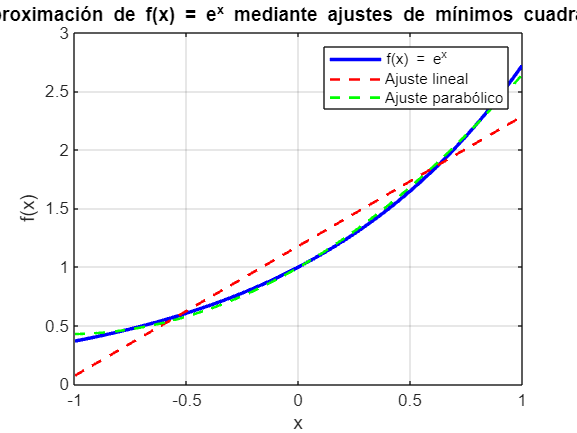

figure;
plot(x, y, 'b', 'LineWidth', 2);  % Función original en azul
hold on;
plot(x, Y_ajuste_linea, 'r--', 'LineWidth', 1.5);  % Ajuste lineal en rojo
plot(x, Y_ajuste_parabola, 'g--', 'LineWidth', 1.5);  % Ajuste parabólico en verde
legend('f(x) = e^x', 'Ajuste lineal', 'Ajuste parabólico');
xlabel('x');
ylabel('f(x)');
title('Aproximación de f(x) = e^x mediante ajustes de mínimos cuadrados');
grid on;

Observamos que el ajuste con la parábola ofrece una representación más cercana ya que captura parte de su curvatura, proporcionando una aproximación más precisa. 

#### • Aproxime la función f(x) = 1/x en el intervalo [1, 2] mediante:

x = linspace(1, 2, 100);
y = 1./x;

– Una recta de mínimos cuadrados. 

[m, b] = ajusteLinealMinimosCuadrados(x, y);

fprintf('La ecuación de la línea recta ajustada es: y = %.4fx + %.4f\n', m, b);

La ecuación de la línea recta ajustada es: y = -0.4774x + 1.4098



Y_ajustado_recta = m * x + b;

– Una parábola de mínimos cuadrados. 

[a, b,c] = ajusteParabola(x, y);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('El valor ajustado de a es: %.4f\n', a);

El valor ajustado de a es: 0.3281


fprintf('El valor ajustado de b es: %.4f\n', b);

El valor ajustado de b es: -1.4616


fprintf('El valor ajustado de c es: %.4f\n', c);

El valor ajustado de c es: 2.1200



Y_ajustado_parabola = a * x.^2 + b * x + c;

– Una ecuacion cúbica de mínimos cuadrados.

coeficientes_cubica = ajustePolinomial(x, y, 3);
Y_ajustado_cubica = coeficientes_cubica(1) * x.^3 + coeficientes_cubica(2) * x.^2 + coeficientes_cubica(3) * x + coeficientes_cubica(4);

– Compare gráficamente los resultados.

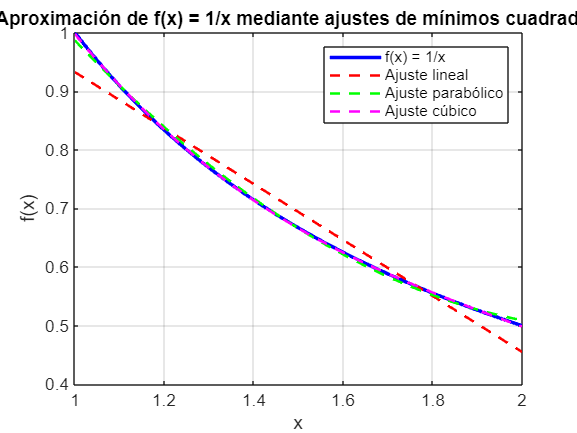

figure;
plot(x, y, 'b', 'LineWidth', 2);  % Función original en azul
hold on;
plot(x, Y_ajustado_recta, 'r--', 'LineWidth', 1.5);  % Ajuste lineal en rojo
plot(x, Y_ajustado_parabola, 'g--', 'LineWidth', 1.5);  % Ajuste parabólico en verde
plot(x, Y_ajustado_cubica, 'm--', 'LineWidth', 1.5);  % Ajuste cúbico en magenta
legend('f(x) = 1/x', 'Ajuste lineal', 'Ajuste parabólico', 'Ajuste cúbico');
xlabel('x');
ylabel('f(x)');
title('Aproximación de f(x) = 1/x mediante ajustes de mínimos cuadrados');
grid on;

#### • Aproxime la función f(x) = (2x)^3 en el intervalo [0, 1] mediante: 

x = linspace(0, 1, 100);
y = (2*x).^3;

– Una recta de mínimos cuadrados. 

[m, b] = ajusteLinealMinimosCuadrados(x, y);

fprintf('La ecuación de la línea recta ajustada es: y = %.4fx + %.4f\n', m, b);

La ecuación de la línea recta ajustada es: y = 7.2241x + -1.5918



Y_ajustado_recta = m * x + b;

– Una parábola de mínimos cuadrados. 

[a, b,c] = ajusteParabola(x, y);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('El valor ajustado de a es: %.4f\n', a);

El valor ajustado de a es: 12.0000


fprintf('El valor ajustado de b es: %.4f\n', b);

El valor ajustado de b es: -4.7759


fprintf('El valor ajustado de c es: %.4f\n', c);

El valor ajustado de c es: 0.3880



Y_ajustado_parabola = a * x.^2 + b * x + c;

– Compare gráficamente los resultados.

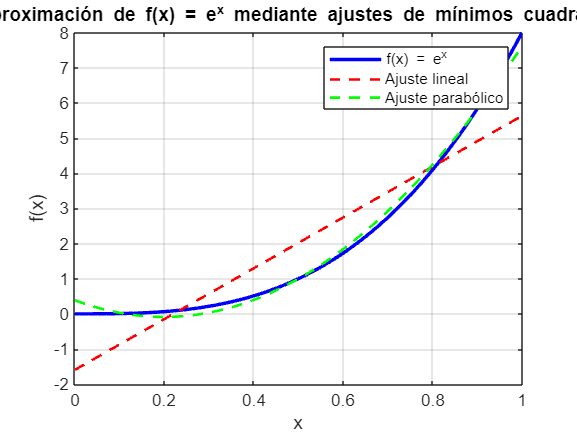

figure;
plot(x, y, 'b', 'LineWidth', 2);  % Función original en azul
hold on;
plot(x, Y_ajustado_recta, 'r--', 'LineWidth', 1.5);  % Ajuste lineal en rojo
plot(x, Y_ajustado_parabola, 'g--', 'LineWidth', 1.5);  % Ajuste parabólico en verde
legend('f(x) = e^x', 'Ajuste lineal', 'Ajuste parabólico');
xlabel('x');
ylabel('f(x)');
title('Aproximación de f(x) = e^x mediante ajustes de mínimos cuadrados');
grid on;
hold off

### d.

#### • A continuación se muestra la gráfica de una función, la cual se aproxima usando series de Fourier:

syms x
f1 = @(x) x + 2;
f2 = @(x) -x;
f3 = @(x) x;
f4 = @(x) -x + 2;
f5 = @(x) x - 2;
f6 = @(x) -x + 4;

intervalos = [-2, -1; -1, 0; 0, 1; 1, 2; 2, 3; 3, 4];

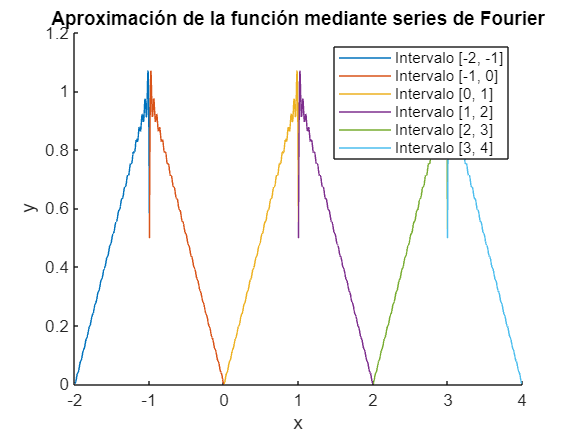

a = -2;
b = 4;
N = 50;
num_puntos = 1000;

figure;
hold on;

% Aproximación de Fourier para cada intervalo
for i = 1:size(intervalos, 1)
    a_i = intervalos(i, 1);
    b_i = intervalos(i, 2);
    
    % Seleccionar la función correspondiente al intervalo
    if i == 1
        f = @(x) x + 2;
    elseif i == 2
        f = @(x) -x;
    elseif i == 3
        f = @(x) x;
    elseif i == 4
        f = @(x) -x + 2;
    elseif i == 5
        f = @(x) x - 2;
    elseif i == 6
        f = @(x) -x + 4;
    end
    
    % Aproximación de Fourier para el intervalo actual
    [X, Y_aprox] = aproximacionFourier(f, a_i, b_i, N, num_puntos);
    
    % Graficar aproximación de Fourier
    plot(X, Y_aprox);
end

hold off;
xlabel('x');
ylabel('y');
title('Aproximación de la función mediante series de Fourier');
legend('Intervalo [-2, -1]', 'Intervalo [-1, 0]', 'Intervalo [0, 1]', 'Intervalo [1, 2]', 'Intervalo [2, 3]', 'Intervalo [3, 4]');

#### • La siguiente tabla muestra los datos a ser aproximados usando series de Fourier: 

x = [0:0.1:3.5];
Y = [1.9990, 0.5253, 0.8726, 0.8509, -0.1269, 0.0000, ...
    0.0000, -0.8509, -0.8726, -0.5253, 1.9990, -0.5253,...
    -0.8726, -0.8509, 0.1269, 0.0000, -0.1269, 0.0000,...
    0.8726, 0.5253, 0.1269, 0.5253, 0.8726, -0.1269,...
    -0.1269, 0.0000, 0.1269, -0.8509, 0.8726, -0.5253, ...
    0.0000, -0.5253, -0.8726, -0.8509, 0.1269, 0.0000];


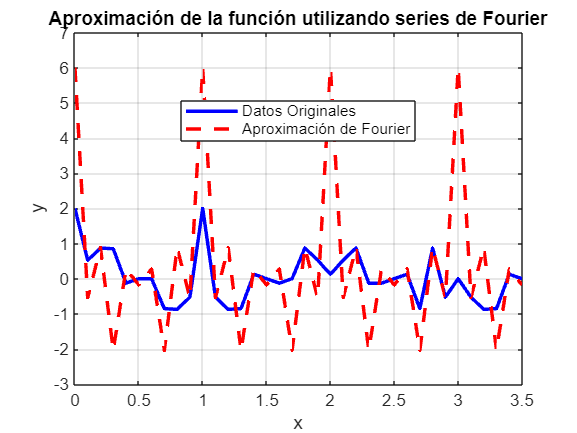

grado = 30;
y_aprox = aproximaFourier(x, Y, grado);

% Graficar los resultados
figure;
plot(x, Y, 'b', 'LineWidth', 2);
hold on;
plot(x, y_aprox, 'r--', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Aproximación de la función utilizando series de Fourier');
legend('Datos Originales', 'Aproximación de Fourier', 'Location', 'best');
grid on;

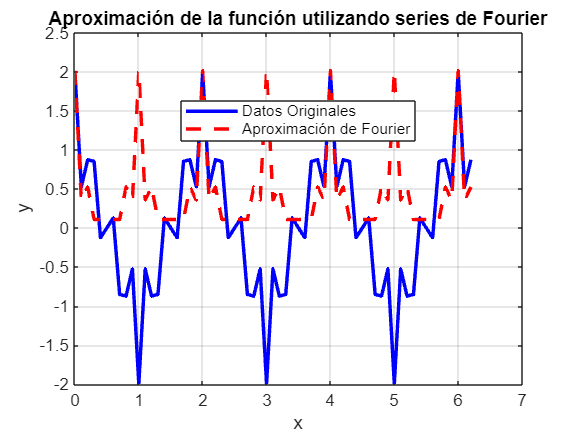

x1 = 0:0.1:6.2;
y1 = [1.9990 0.5253 0.8726 0.8509 -0.1269 0.0000 0.1269 -0.8509 -0.8726 -0.5253 -1.9990 -0.5253 -0.8726 -0.8509 0.1269 0.0000 -0.1269 0.8509 0.8726 0.5253 1.9990 0.5253 0.8726 0.8509 -0.1269 0.0000 0.1269 -0.8509 -0.8726 -0.5253 -1.9990 -0.5253 -0.8726, -0.8509 0.1269 0.0000 -0.1269 0.8509 0.8726 0.5253 1.9990 0.5253 0.8726 0.8509 -0.1269 0.0000 0.1269 -0.8509 -0.8726 -0.5253 -1.9990 -0.5253 -0.8726 -0.8509 0.1269 0 -0.1269 0.8509 0.8726 0.5253 1.9990 0.5253 0.8726];

grado = 30;
y_aprox1 = aproximaFourier(x1, y1, grado);

% Graficar los resultados
figure;
plot(x1, y1, 'b', 'LineWidth', 2);
hold on;
plot(x1, y_aprox1, 'r--', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Aproximación de la función utilizando series de Fourier');
legend('Datos Originales', 'Aproximación de Fourier', 'Location', 'best');
grid on;